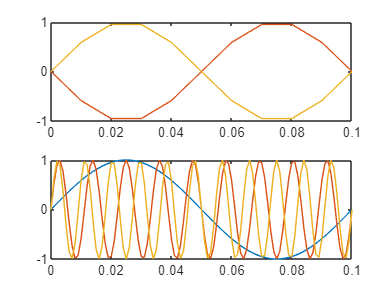

clear variables

f1=10; f2=90; f3=110;
T1=0.01; t=0:T1:0.1; %T1 not sufficiently small
subplot(211)
plot(t,sin(2*pi*f1*t),t,sin(2*pi*f2*t),t,sin(2*pi*f3*t))

f1=10; f2=90; f3=110;
T1=0.001; t=0:T1:0.1; %T1 not sufficiently small
subplot(212)
plot(t,sin(2*pi*f1*t),t,sin(2*pi*f2*t),t,sin(2*pi*f3*t))

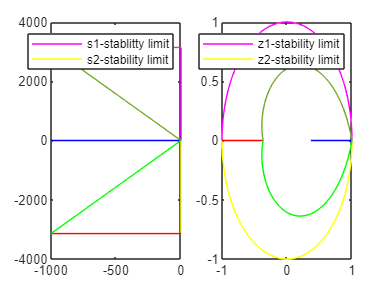

Ts=1e-3;
s1=j*linspace(0,pi/Ts,1e3); 
s2=-s1;
s3 = linspace(0,-1000,100);
s4 = linspace(0,-1000,100)+pi/Ts*j;
s5 = linspace(0,-1000,100)-pi/Ts*j;
s6 = linspace(0,-1000,100)+linspace(0,pi/Ts,100)*j;
s7 = linspace(0,-1000,100)+linspace(0,-pi/Ts,100)*j;
z1 = exp(s1*Ts);
z2 = exp(s2*Ts);
z3 = exp(s3*Ts);
z4 = exp(s4*Ts);
z5 = exp(s5*Ts);
z6 = exp(s6*Ts);
z7 = exp(s7*Ts);
figure,
subplot(121);
plot(real(s1),imag(s1),'m'); hold on
plot(real(s2),imag(s2),'y'); 
plot(real(s3),imag(s3),'b'); 
plot(real(s4),imag(s4),'Color',[0.8500 0.3250 0.0980]);
plot(real(s5),imag(s5),'r');
plot(real(s6),imag(s6),'Color',[0.4660 0.6740 0.1880]);
plot(real(s7),imag(s7),'g'); 
legend('s1-stablitty limit','s2-stability limit');
subplot(122);
plot(real(z1),imag(z1),'m'); hold on
plot(real(z2),imag(z2),'y'); 
plot(real(z3),imag(z3),'b'); 
plot(real(z4),imag(z4),'Color',[0.8500 0.3250 0.0980]);
plot(real(z5),imag(z5),'r');
plot(real(z6),imag(z6),'Color',[0.4660 0.6740 0.1880]);
plot(real(z7),imag(z7),'g');
legend('z1-stability limit','z2-stability limit')


%%damping factor zeta > 1 
%%damping factor zeta = 1 
%%damping factor 0 < zeta < 1 
%%damping factor zeta = 0